syms f(g)
f(g) = 0;
z = [ 9.27185689e-30 -2.69196802e-25  3.33277639e-21 -2.29855128e-17 9.68752486e-14 -2.57578506e-10  4.28980804e-07 -4.25098468e-04 2.31965986e-01  7.85901406e-03];
for i=1:(length(z))
    f(g) = f(g) + z(i)*(g^(length(z)-i));
end
R=287;
Ru=8.314;
LHV=42.588e6;
P_atm=101325;
rho_atm=1.2923;
gamma=1.4;
cp=1.005e3;
cv=cp/gamma;
T_atm=300;
S=80*10^-3; %Stroke
Rad=S/2; %radius of crank
L=S*1.75; %length of connecting rod
r=18.5; %compression ratio
Bore=76.5*10^-3; % bore of cylinder
LIFT_MAX=4.5*10^-3; % Maximum Lift
Vd=(pi*(Bore^2)*Rad)/2

Vd = 3.6771e-04

Vcl=Vd/(r-1);
%S=(Vd*4)/((Bore^2)*pi);

N=5000 %engine rpm

N = 5000


W= (2*pi*N)/60

W = 523.5988

CM=(N*2*Rad)/30; % Mean Piston Speed
IVO=pi/12; % IVO Before TDC
IVC=pi/9; % IVC After BDC
EVO=pi/9; % EVO before BDC
EVC=IVO; % EVC after TDC
D=30*10^-3; % Inlet Valve Diameter
D2=2*D; % Inlet manifold diameter
A1=pi*0.25*D^2;
A2=pi*0.25*D2^2;
FIS=pi/36; %fuel injection starts before TDC
FIC=pi/7.2; %fuel injector closes after TDC
MWair=0.02987;
dtheta=0.0002;
a=0.137;
b=0.0387e-3;
stoichiometric_af_ratio=14.5;
%--------------------------------------------------------------------------%
%--------------Modelling of Intake-----------------------------------------%
%--------------------------------------------------------------------------%
theta_i=(-IVO:dtheta:pi+IVC);
N_i = length(theta_i);
P_i=zeros(1,N_i);
dP_i=zeros(1,N_i);
T_i=zeros(1,N_i);
V_i=Vd*((r/(r-1)) - ((1-cos(theta_i - pi))/2) + (L/S) - 0.5*sqrt((2*L/S)^2 - (sin(theta_i - pi)).^2));
dV_i=gradient(V_i,dtheta)

dV_i = 1.0e-03 *

   -0.0607   -0.0607   -0.0607   -0.0606   -0.0606   -0.0605   -0.0605   -0.0604   -0.0604   -0.0604   -0.0603   -0.0603   -0.0602   -0.0602   -0.0601   -0.0601   -0.0600   -0.0600   -0.0599   -0.0599   -0.0599   -0.0598   -0.0598   -0.0597   -0.0597   -0.0596   -0.0596   -0.0595   -0.0595   -0.0595   -0.0594   -0.0594   -0.0593   -0.0593   -0.0592   -0.0592   -0.0591   -0.0591   -0.0591   -0.0590   -0.0590   -0.0589   -0.0589   -0.0588   -0.0588   -0.0587   -0.0587   -0.0586   -0.0586   -0.0586


m_i=zeros(1,N_i);
avg_cyl_gas_velocity=2.28*CM;
dm_i=zeros(1,N_i);
Twall=400;
T_im=300;
P_m=101325;
P_im=90000;
A_i= (pi*Bore^2)/2 + (pi*Bore*S/2)*(1 - cos(theta_i) + (L/Rad) - sqrt((L/Rad)^2 - (sin(theta_i)).^2));
P_i(1)=P_m;
T_i(1)=T_im;
m_i(1)=(P_i(1)*V_i(1))/(T_i(1)*(Ru/MWair));
%{
U_v=((pi/4)*Bore^2*CM)/(A1);
rho=m_i(1)/V_i(1)
P_im = P_i(1) + (0.5*rho*U_v*U_v);
%}
for i=1:N_i-1
    cv = 0.2*T_i(i) + 700;
    cp = R+cv;
    gamma=cp/cv;
    CD=(107.78*((LIFT_MAX/D)^4))-(77.204*((LIFT_MAX/D)^3))+(14.1*((LIFT_MAX/D)^2))-(1.01*(LIFT_MAX/D))+0.6687;
    CURTAREA=(pi/4)*D^2;
    Cht=3.26*(10^-3)*(P_i(i)^(0.8))*(T_i(i)^(-0.55))*(Bore^(-0.2))*(avg_cyl_gas_velocity^(0.8));
    if P_i(i)<=P_im
        if (P_i(i)/P_im)<=(2/(gamma+1))^(gamma/(gamma-1))
            dm_i(i)=(P_im/(sqrt(R*T_im)))*((sqrt(gamma))*((2*gamma/(gamma+1))^((gamma+1)/2*(gamma-1))))*CD*CURTAREA/W;
            m_i(i+1)=(dtheta*dm_i(i))+m_i(i);
        else
            dm_i(i)=(P_im/(sqrt(R*T_im)))*(((P_i(i)/P_im)^(1/gamma))*sqrt((2*gamma/(gamma-1))*(1 - (P_i(i)/P_im)^((gamma-1)/gamma))))*CD*CURTAREA/W;
            m_i(i+1)=(dtheta*dm_i(i))+m_i(i);
            
        end
        n=m_i(i)/MWair;
        dP_i(i) = ((W*dm_i(i)*cp*T_i(i))-A_i(i)*Cht*(T_i(i)-Twall) - W*dV_i(i)*(P_i(i)*(1 + cv/(R)) + 2*a*b*n*n*n*cv/(R*((V_i(i))^3)) - a*n*n*cv/(R*((V_i(i))^2))))/(W*(V_i(i)*cv/(R) - cv*b*n/R));
        P_i(i+1)=(dtheta*dP_i(i))+P_i(i);
        T_i(i+1)=(P_i(i+1)*V_i(i+1))/(m_i(i+1)*(Ru/MWair));
    else
        if (P_im/P_i(i))<=(2/(gamma+1))^(gamma/(gamma-1))
            dm_i(i)=-(P_i(i)/sqrt(R*T_i(i)))*((sqrt(gamma))*((2*gamma/(gamma+1))^((gamma+1)/2*(gamma-1))))*CD*CURTAREA/W;
            m_i(i+1)=(dtheta*dm_i(i))+m_i(i);
        else
            dm_i(i)=(P_i(i)/sqrt(R*T_i(i)))*(((P_im/P_i(i))^(1/gamma))*sqrt((2*gamma/(gamma-1))*(1 - (P_im/P_i(i))^((gamma-1)/gamma))))*CD*CURTAREA/W;
            m_i(i+1)=(dtheta*dm_i(i))+m_i(i);
        end
        n=m_i(i)/MWair;
        dP_i(i) = (W*dm_i(i)*cp*T_i(i) - W*dV_i(i)*(P_i(i)*(1 + cv/(R)) + 2*a*b*n*n*n*cv/(R*((V_i(i))^3)) - a*n*n*cv/(R*((V_i(i))^2))))/(W*(V_i(i)*cv/(R) - cv*b*n/R));
        P_i(i+1)=(dtheta*dP_i(i))+P_i(i);
        T_i(i+1)=(P_i(i+1)*V_i(i+1))/(m_i(i+1)*(Ru/MWair));
    end
    %{
    rho=m_i(i+1)/V_i(i+1);
    P_im = P_i(i+1) + (0.5*rho*U_v*U_v);
    %}
end
vol_eff = double(f(N))

vol_eff = 82.1749

mai = double(f(N)*Vd*rho_atm/100)

mai = 3.9049e-04

m_i(N_i) = mai;
mass_of_air_inducted = mai

mass_of_air_inducted = 3.9049e-04

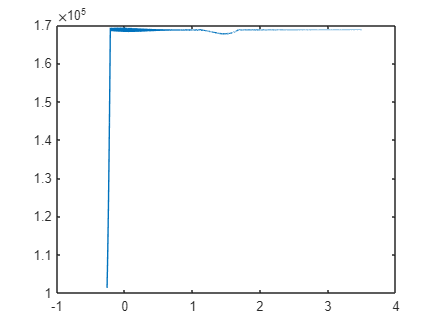

plot(theta_i,P_i)

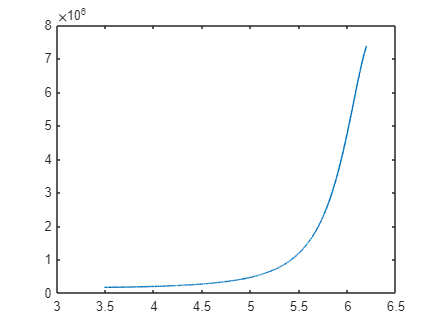

%--------------------------------------------------------------------------%
%----------------------Modelling of Compression----------------------------%
%--------------------------------------------------------------------------%
theta_c=(pi+IVC:dtheta:2*pi - FIS);
N_c = length(theta_c);
P_c=zeros(1,N_c);
dP_c=zeros(1,N_c);
T_c=zeros(1,N_c);
V_c=Vd*((r/(r-1)) - ((1-cos(theta_c - pi))/2) + (L/S) - 0.5*sqrt((2*L/S)^2 - (sin(theta_c - pi)).^2));
dV_c=gradient(V_c,dtheta);
A_c= (pi*Bore^2)/2 + (pi*Bore*S/2)*(1 - cos(theta_c) + (L/Rad) - sqrt((L/Rad)^2 - (sin(theta_c)).^2));
Twall=400;
avg_cyl_gas_velocity=2.28*CM;
n = m_i(N_i)/MWair;
T_c(1)=T_i(N_i);
P_c(1)=P_i(N_i);
for i=1:N_c-1
    cv = 0.2*T_c(i) + 700;
    Cht=3.26*(10^-3)*(P_c(i)^(0.8))*(T_c(i)^(-0.55))*(Bore^(-0.2))*(avg_cyl_gas_velocity^(0.8));
    dP_c(i) = -(A_c(i)*Cht*(T_c(i)-Twall) + W*dV_c(i)*(P_c(i)*(1 + cv/(R)) + 2*a*b*n*n*n*cv/(R*((V_c(i))^3)) - a*n*n*cv/(R*((V_c(i))^2))))/(W*(V_c(i)*cv/(R) - cv*b*n/R));
    P_c(i+1)=(dtheta*dP_c(i))+P_c(i);
    T_c(i+1)=(P_c(i+1)*V_c(i+1))/(Ru*n);
end
plot(theta_c,P_c)

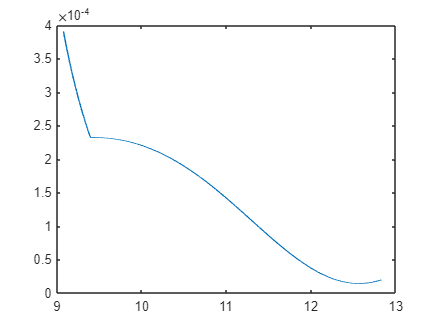

%--------------------------------------------------------------------------%
%---------------------Modelling of Combustion------------------------------%
%--------------------------------------------------------------------------%
theta_b=(2*pi - FIS:dtheta:2*pi + FIC +0.15);
N_b = length(theta_b);
P_b=zeros(1,N_b);
dP_b=zeros(1,N_b);
T_b=zeros(1,N_b);
dqc=zeros(1,N_b);
V_b=Vd*((r/(r-1)) - ((1-cos(theta_b - pi))/2) + (L/S) - 0.5*sqrt((2*L/S)^2 - (sin(theta_b - pi)).^2));
dV_b=gradient(V_b,dtheta);
A_b= (pi*Bore^2)/2 + (pi*Bore*S/2)*(1 - cos(theta_b) + (L/Rad) - sqrt((L/Rad)^2 - (sin(theta_b)).^2));
Twall=1200;
avg_cyl_gas_velocity=2.28*CM;
n = m_i(N_i)/MWair;
lambda=1.517; %equivalence air-fuel ratio
mfuel=m_i(N_i)/(stoichiometric_af_ratio*lambda);
qav = LHV*mfuel;
ab=6.908;
comb_dur=FIC+FIS+0.15;
mb=2.36;
T_b(1)=T_c(N_c);
P_b(1)=P_c(N_c);
for i=1:N_b-1
    cv = 0.2*T_b(i) + 700;
    Cht=3.26*(10^-3)*(P_b(i)^(0.8))*(T_b(i)^(-0.55))*(Bore^(-0.2))*(avg_cyl_gas_velocity^(0.8));
    dqc(i) = ab*W*(mb+1)*((qav*pi/(180*comb_dur))^mb)*(((theta_b(i) - (2*pi-FIS))/comb_dur)^mb)*exp(-ab*(((theta_b(i) - (2*pi-FIS))/comb_dur)^(mb+1)));
    dP_b(i) = (dqc(i) - A_b(i)*Cht*(T_b(i)-Twall) - W*dV_b(i)*(P_b(i)*(1 + cv/(R)) + 2*a*b*n*n*n*cv/(R*((V_b(i))^3)) - a*n*n*cv/(R*((V_b(i))^2))))/(W*(V_b(i)*cv/(R) - cv*b*n/R));
    P_b(i+1)=(dtheta*dP_b(i))+P_b(i);
    T_b(i+1)=(P_b(i+1)*V_b(i+1))/(Ru*n);
end
%--------------------------------------------------------------------------%
%---------------------Modelling of Expansion-------------------------------%
%--------------------------------------------------------------------------%
theta_e=(2*pi + FIC+0.15:dtheta:3*pi - EVO);
N_e = length(theta_e);
P_e=zeros(1,N_e);
dP_e=zeros(1,N_e);
T_e=zeros(1,N_e);
V_e=Vd*((r/(r-1)) - ((1-cos(theta_e - pi))/2) + (L/S) - 0.5*sqrt((2*L/S)^2 - (sin(theta_e - pi)).^2));
dV_e=gradient(V_e,dtheta);
A_e= (pi*Bore^2)/2 + (pi*Bore*S/2)*(1 - cos(theta_e) + (L/Rad) - sqrt((L/Rad)^2 - (sin(theta_e)).^2));
Twall=1100;
avg_cyl_gas_velocity=2.28*CM;
n = m_i(N_i)/MWair;
T_e(1)=T_b(N_b);
P_e(1)=P_b(N_b);
for i=1:N_e-1
    cv = 0.2*T_e(i) + 700;
    Cht=3.26*(10^-3)*(P_e(i)^(0.8))*(T_e(i)^(-0.55))*(Bore^(-0.2))*(avg_cyl_gas_velocity^(0.8));
    dP_e(i) = -(A_e(i)*Cht*(T_e(i)-Twall) + W*dV_e(i)*(P_e(i)*(1 + cv/(R)) + 2*a*b*n*n*n*cv/(R*((V_e(i))^3)) - a*n*n*cv/(R*((V_e(i))^2))))/(W*(V_e(i)*cv/(R) - cv*b*n/R));
    P_e(i+1)=(dtheta*dP_e(i))+P_e(i);
    T_e(i+1)=(P_e(i+1)*V_e(i+1))/(Ru*n);
end
%--------------------------------------------------------------------------%
%---------------------Modelling of Exhuast---------------------------------%
%--------------------------------------------------------------------------%
theta_ex=(3*pi - EVO:dtheta:4*pi+EVC);
N_ex = length(theta_ex);
P_ex=zeros(1,N_ex);
dP_ex=zeros(1,N_ex);
T_ex=zeros(1,N_ex);
V_ex=Vd*((r/(r-1)) - ((1-cos(theta_ex - pi))/2) + (L/S) - 0.5*sqrt((2*L/S)^2 - (sin(theta_ex - pi)).^2));
dV_ex=gradient(V_ex,dtheta);
m_ex=zeros(1,N_ex);
avg_cyl_gas_velocity=6.18*CM;
dm_ex=zeros(1,N_ex);
Twall=700;
T_exm=1000;
P_exm=101325 + 20e3;
A_ex= (pi*Bore^2)/2 + (pi*Bore*S/2)*(1 - cos(theta_ex) + (L/Rad) - sqrt((L/Rad)^2 - (sin(theta_ex)).^2));
P_ex(1)=P_e(N_e);
T_ex(1)=T_e(N_e);
m_ex(1)=m_i(N_i);

for i=1:N_ex-1
    cv = 0.2*T_ex(i) + 700;
    cp = R+cv;
    gamma=cp/cv;
    CD=(107.78*((LIFT_MAX/D)^4))-(77.204*((LIFT_MAX/D)^3))+(14.1*((LIFT_MAX/D)^2))-(1.01*(LIFT_MAX/D))+0.6687;
    CURTAREA=(pi/4)*D^2;
    Cht=3.26*(10^-3)*(P_ex(i)^(0.8))*(T_ex(i)^(-0.55))*(Bore^(-0.2))*(avg_cyl_gas_velocity^(0.8));
    if P_exm<=P_ex(i)
        if (P_exm/P_ex(i))<=(2/(gamma+1))^(gamma/(gamma-1))
            dm_ex(i)=-(P_ex(i)/(sqrt(R*T_ex(i))))*((sqrt(gamma))*((2*gamma/(gamma+1))^((gamma+1)/2*(gamma-1))))*CD*CURTAREA/W;
            m_ex(i+1)=(dtheta*dm_ex(i))+m_ex(i);
        else
            dm_ex(i)=(P_ex(i)/(sqrt(R*T_ex(i))))*(((P_exm/P_ex(i))^(1/gamma))*sqrt((2*gamma/(gamma-1))*(1 - (P_exm/P_ex(i))^((gamma-1)/gamma))))*CD*CURTAREA/W;
            m_ex(i+1)=(dtheta*dm_ex(i))+m_ex(i);
        end
        n=m_ex(i)/MWair;
        dP_ex(i) = ((W*dm_ex(i)*cp*T_ex(i))-A_ex(i)*Cht*(T_ex(i)-Twall)-W*dV_ex(i)*(P_ex(i)*(1 + cv/(R)) + 2*a*b*n*n*n*cv/(R*((V_ex(i))^3)) - a*n*n*cv/(R*((V_ex(i))^2))))/(W*(V_ex(i)*cv/(R) - cv*b*n/R));
        P_ex(i+1)=(dtheta*dP_ex(i))+P_ex(i);
        T_ex(i+1)=(P_ex(i+1)*V_ex(i+1))/(m_ex(i+1)*(Ru/MWair));
    else
        if (P_ex(i)/P_exm)<=(2/(gamma+1))^(gamma/(gamma-1))
            dm_ex(i)=(P_exm/sqrt(R*T_exm))*((sqrt(gamma))*((2*gamma/(gamma+1))^((gamma+1)/2*(gamma-1))))*CD*CURTAREA/W;
            m_ex(i+1)=(dtheta*dm_ex(i))+m_ex(i);
        else
            dm_ex(i)=(P_exm/sqrt(R*T_exm))*(((P_ex(i)/P_exm)^(1/gamma))*sqrt((2*gamma/(gamma-1))*(1 - (P_ex(i)/P_exm)^((gamma-1)/gamma))))*CD*CURTAREA/W;
            m_ex(i+1)=(dtheta*dm_ex(i))+m_ex(i);
        end
        n=m_ex(i)/MWair;
        dP_ex(i) = (W*dm_ex(i)*cp*T_ex(i)-W*dV_ex(i)*(P_ex(i)*(1 + cv/(R)) + 2*a*b*n*n*n*cv/(R*((V_ex(i))^3)) - a*n*n*cv/(R*((V_ex(i))^2))))/(W*(V_ex(i)*cv/(R) - cv*b*n/R));
        P_ex(i+1)=(dtheta*dP_ex(i))+P_ex(i);
        T_ex(i+1)=(P_ex(i+1)*V_ex(i+1))/(m_ex(i+1)*(Ru/MWair));
    end
end
plot(theta_ex,m_ex)

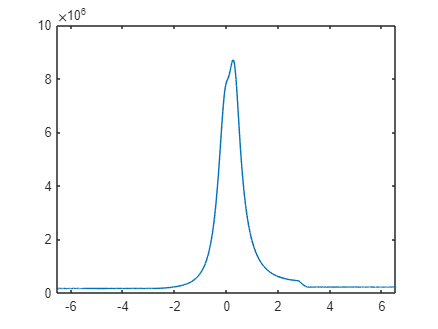

%--------------------------------------------------------------------------%

theta =[theta_i theta_c theta_b theta_e theta_ex];
P = [P_i P_c P_b P_e P_ex];
V = [V_i V_c V_b V_e V_ex];
dV = [dV_i dV_c dV_b dV_e dV_ex];
T = [T_i T_c T_b T_e T_ex];
plot(theta-2*pi,P)

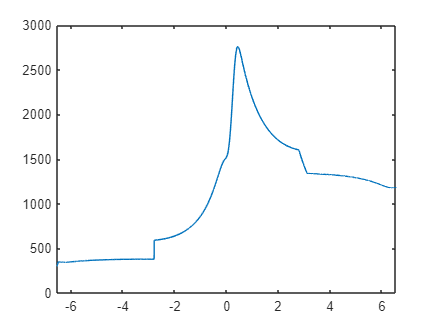

plot(theta-2*pi,T)

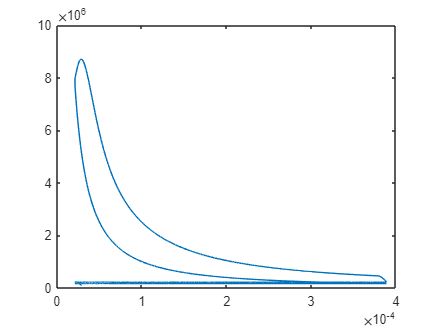

plot((V),(P))

N_t = length(theta);
TWD=0;
for i=1:N_t
    TWD = TWD + P(i)*dV(i)*dtheta;
end
TWD

TWD = 366.3978

IMEP = TWD/Vd

IMEP = 9.9644e+05

IP = IMEP*S*pi*(Bore^2)*N/480

IP = 1.5267e+04

IHP = IP/745.7

IHP = 20.4728